# Aqui vamos de nuevo

Ahora vamos a trabajar con los datos binarios transformados en escalas de grises:

img_grey = readNPY("C:\Users\marlo\OneDrive - Pontificia Universidad Javeriana\Maestria_IA\2130 Sistemas Inteligentes\Proyecto\Dataset\Imagenes_gris_240.npy");
img_grey = double(img_grey);

 Ahora tambien vamos a importar las etiquetas

etiquetas = readNPY("C:\Users\marlo\OneDrive - Pontificia Universidad Javeriana\Maestria_IA\2130 Sistemas Inteligentes\Proyecto\Dataset\labels.npy");
etiquetas = double(etiquetas);

Ahora ya tenemos los datos importados. 

Vamos a utilizar la funcion '*fitrnet*' utilizada en los ejemplos de *Matlab. *Ahora vamos a partir los datos en sets para entrenar y para hacer test.

rng("default") % Este es para establecer la semilla para reproducibilidad.
c = cvpartition(length(etiquetas), "HoldOut", 0.20); % separar el 20% para pruebas, se crean los indices
trainingIdx = training(c); % Indices por el conjunto de entrenamiento
XTrain = img_grey(trainingIdx,:); % subset de acuerdo a los indices de entrenamiento 
YTrain = etiquetas(trainingIdx);
testIdx = test(c); % indices para el conjunto de datos de prueba
XTest = img_grey(testIdx,:);
YTest = etiquetas(testIdx);

una ves hemos separado los conjuntos de datos en entrenamiento y pruebas, vamos a entrenar el modelo de regresión de Red Neuronal. 

Va a tener las siguiente especificaciones: va a tener 30 salidas en la primera capa y 10 salidas en las segunda. Por defecto ambas capas van a usar un ReLU (Rectified Linear Unit) como funcion de activación. 

modelo = fitrnet(XTrain,YTrain, "Standardize", true, "LayerSizes", [30 10])

modelo =   RegressionNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 1600
               LayerSizes: [30 10]
              Activations: 'relu'
    OutputLayerActivation: 'linear'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [166×7 table]


  Properties, Methods


una vez el modelo está entrenado, vamos a consultar los pesos y 'Biases', los primeros dos elementos corresponden a los valores de las capas totalmente conectadas.  

modelo.LayerWeights{1}

ans =     0.0050    0.0088    0.0049   -0.0070    0.0099   -0.0054    0.0033   -0.0039   -0.0010   -0.0034   -0.0076   -0.0065   -0.0091   -0.0102   -0.0086    0.0057    0.0043    0.0077   -0.0031   -0.0071   -0.0132   -0.0141    0.0033   -0.0044    0.0046   -0.0044   -0.0138    0.0003   -0.0165   -0.0055   -0.0027   -0.0001   -0.0078    0.0066    0.0036    0.0008   -0.0061    0.0014    0.0035   -0.0119   -0.0094   -0.0086    0.0025    0.0035    0.0050    0.0011    0.0021   -0.0089    0.0025   -0.0012
    0.0080    0.0054    0.0053   -0.0054    0.0015    0.0035   -0.0016    0.0008    0.0057    0.0102    0.0100    0.0113    0.0008   -0.0013    0.0106    0.0011    0.0071    0.0078    0.0066   -0.0001    0.0025    0.0073    0.0058    0.0111    0.0116    0.0118    0.0080    0.0042   -0.0004   -0.0051   -0.0004    0.0107   -0.0021    0.0032   -0.0015    0.0117    0.0007   -0.0054   -0.0063    0.0043   -0.0016    0.0045   -0.0039    0.0100    0.0108    0.0022   -0.0026    0.0022    0.0036   

La capa final tiene una sola salida. El numero de capas corresponden a la primera dimension de la capa de pesos y Biases. 

size(modelo.LayerWeights{end})

ans =      1    10


Ahora vamos a calcular el desempeño del modelo entrenado. Calculamos el error cuadrado medio (Mean Squared Error MSE) de los datos de prueba.

Un error pequeño indica mejor performance:

testMSE = loss(modelo, XTest, YTest)

testMSE = 28.3291

Comparar los valores de prueba contra los valores reales en una grafica. Vertical los datos pronosticas y en el horizontal los datos reales.

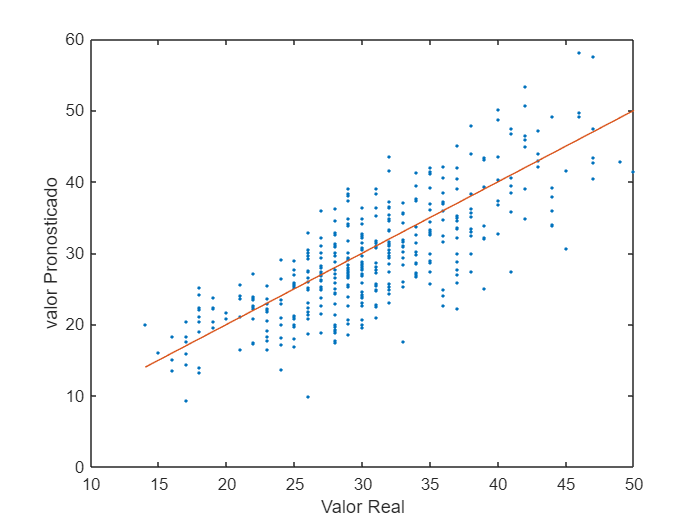

testPredictions = predict(modelo, XTest);
plot(YTest, testPredictions, ".");
hold on
plot(YTest, YTest)
hold off
xlabel("Valor Real")
ylabel("valor Pronosticado")

Aqui podemos probar con Hiperparametros de Optimizacion.